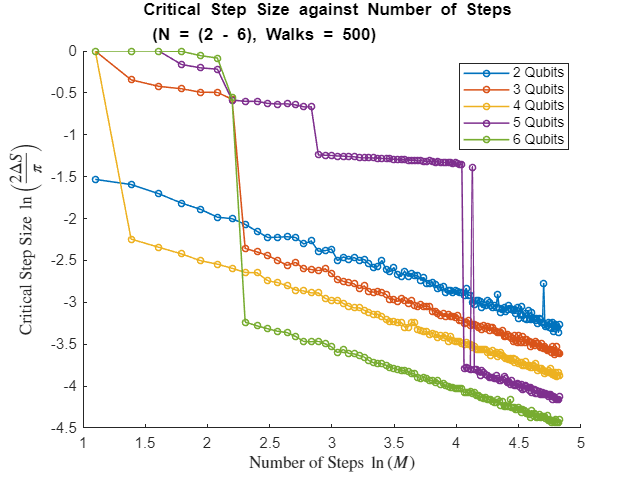

2 Qubits: B(N) = 0.483273, A(N) = 0.606945
3 Qubits: B(N) = 0.798734, A(N) = 1.687887
4 Qubits: B(N) = 0.553796, A(N) = 0.453775
5 Qubits: B(N) = 1.581081, A(N) = 53.404860
6 Qubits: B(N) = 0.999671, A(N) = 1.705608


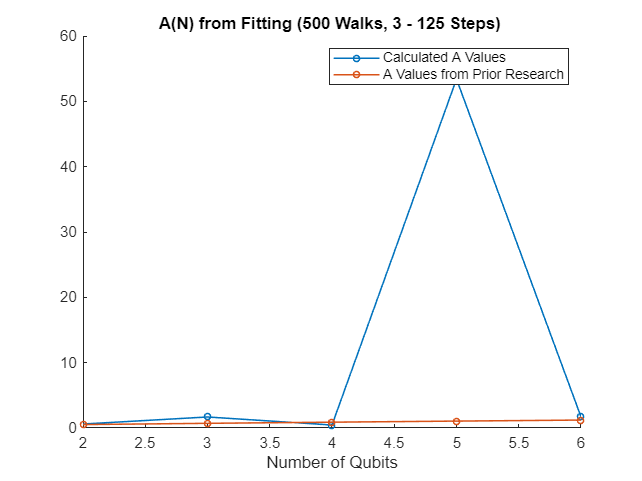

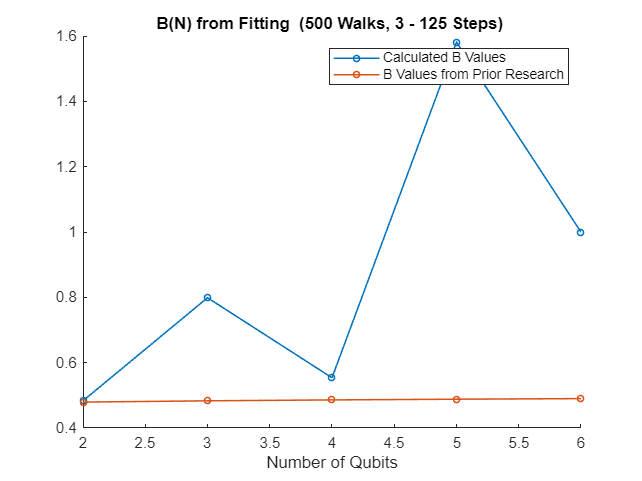

Number_of_Qubits = 6;
Number_of_Walks = 500;

Minimum_Number_of_Steps = 3;
Maximum_Number_of_Steps = 125; 

Step_Size_Resolution = 1e-4;

Distribution = 'maxwell boltzmann';
Poissonian_Mean = 1;

switch lower(Distribution)
    case 'normal'
        Distribution_Sampler = @(n) randn(1, n);

    case 'maxwell boltzmann'
        Distribution_Sampler = @(N, n) sqrt(sum(randn(2^(N+1)-2, n).^2, 1));

    case 'poisson'
    Poisson_Samples = poissrnd(Poissonian_Mean, 1, n);
    Distribution_Sampler = @(n) 1./Poisson_Samples;

    otherwise
        error('Unknown distribution has been specified.');
end

for i = 1:length(Minimum_Number_of_Steps)

Parameter_Fitting_Algorithm(Number_of_Qubits, Number_of_Walks, Minimum_Number_of_Steps(i), Maximum_Number_of_Steps, Step_Size_Resolution, Distribution_Sampler);
end

function FP = Parameter_Fitting_Algorithm(Number_of_Qubits, Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps, Step_Size_Resolution, Distribution_Sampler)

FP = zeros(Number_of_Qubits-1, 2);

Critical_Step_Sizes = Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps, Step_Size_Resolution, Distribution_Sampler);

figure;
hold on;
for j = 1:(Number_of_Qubits-1)

    

    plot(log(Minimum_Number_of_Steps:Maximum_Number_of_Steps), log((2/pi)*Critical_Step_Sizes(j, :)), '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', sprintf('%d Qubits', j+1));
    
    xlabel('Number of Steps $ \ln \left( M \right) $', 'Interpreter', 'latex');
    ylabel('Critical Step Size $ \ln \left( \frac{2 \Delta S}{\pi} \right) $', 'Interpreter', 'latex');
    title(sprintf('Critical Step Size against Number of Steps \\newline (N = (2 - %d), Walks = %d)', Number_of_Qubits, Number_of_Walks));
    legend;

    

end
hold off;
drawnow;

B = zeros(Number_of_Qubits-1, 1);
A = zeros(Number_of_Qubits-1, 1);

A_Paper = zeros(Number_of_Qubits-1, 1); 
B_Paper = zeros(Number_of_Qubits-1, 1);

for j = 1:(Number_of_Qubits-1)

    Data_Set = Critical_Step_Sizes(j, :);
    FP(j,:) = polyfit(log(Minimum_Number_of_Steps:Maximum_Number_of_Steps), log(Data_Set), 1);
    
    B(j) = FP(j,1);
    A(j) = exp(FP(j,2));

    A_Paper(j) = 0.3098 * (j+1)^0.762; 
    B_Paper(j) = 0.4727 * (j+1)^0.020;
    
    fprintf('%d Qubits: B(N) = %f, A(N) = %f\n', j+1, -B(j), A(j));
end  

figure;
hold on;
plot(2:Number_of_Qubits, A(:,1), '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Calculated A Values');
plot(2:Number_of_Qubits, A_Paper(:,1), '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'A Values from Prior Research');
legend;
xlabel('Number of Qubits');
title(sprintf('A(N) from Fitting (%d Walks, %d - %d Steps) ', Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps));
hold off;

figure;
hold on;
plot(2:Number_of_Qubits, -B(:,1), '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Calculated B Values');
plot(2:Number_of_Qubits, B_Paper(:,1), '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'B Values from Prior Research');
legend;
xlabel('Number of Qubits');
title(sprintf('B(N) from Fitting  (%d Walks, %d - %d Steps) ', Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps));
hold off; 


% date_time = datetime('now', 'Format', 'MMMM d, yyyy');

% CSS_Filename = [char(date_time),'_', num2str(Minimum_Number_of_Steps), '_CSS_data_replication.txt'];
% A_Filename = [char(date_time),'_', num2str(Minimum_Number_of_Steps), '_A_Values_data_replication.txt'];
% B_Filename = [char(date_time),'_', num2str(Minimum_Number_of_Steps), '_B_Values_data_replication.txt'];
% 
% writematrix(Critical_Step_Sizes, CSS_Filename)
% writematrix(A, A_Filename)
% writematrix(B, B_Filename)

end


function Data = Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps, Step_Size_Resolution, Distribution_Sampler)

Data = zeros((Number_of_Qubits-1), (Maximum_Number_of_Steps - Minimum_Number_of_Steps));

    for N = 2:Number_of_Qubits
    
        Precision = pi*0.5 - acos(1/sqrt(2^N));
    
        for M = Minimum_Number_of_Steps:Maximum_Number_of_Steps

        %------- Bisection Root Finding Algorithm -------%

            Lower_Bound = 0;
            Upper_Bound = pi/2;

            Critical_Step_Size = 0;

            while abs(Lower_Bound-Upper_Bound) > Step_Size_Resolution

               Midpoint = (Lower_Bound+Upper_Bound)/2;
               Midpoint_Value = Random_Walk_Algorithm(N, M, Number_of_Walks, Midpoint, Distribution_Sampler) - Precision;
        
                   if abs(Midpoint_Value) <= Step_Size_Resolution
        
                        Critical_Step_Size = Midpoint;
                        break

                   elseif (Midpoint_Value) < 0

                        Upper_Bound = Midpoint;  
                   else

                        Lower_Bound = Midpoint;  
                   end

            end
            
            if Critical_Step_Size == 0
            Critical_Step_Size = (Lower_Bound + Upper_Bound)/2;
            end

            Data(N-1,(M- (Minimum_Number_of_Steps-1))) = Critical_Step_Size;
        end 
    end
end

function RWA = Random_Walk_Algorithm(Number_of_Qubits, Number_of_Steps, Number_of_Walks, Step_Size, Distribution_Sampler)

    Final_Distances = zeros(1,Number_of_Walks);

    Dimensions = 2^Number_of_Qubits;
    Component_Volume = Number_of_Walks*Number_of_Steps;
    
    Pole_Vector = zeros(Dimensions, 1);
    Pole_Vector(1) = 1; 
    
    Vector_Database = randn(Dimensions, Component_Volume)+1i*randn(Dimensions, Component_Volume);
    Step_Size_Database = Step_Size*Distribution_Sampler(Number_of_Qubits,Component_Volume);

    for i = 1:Number_of_Walks
     
            Vector = Pole_Vector; 
        
                    for j = 1:Number_of_Steps

                        Selected_Vector = Vector_Database(:,j+(i-1)*Number_of_Steps);

                        Orthogonal_Vector = Selected_Vector - dot(Vector,Selected_Vector)*Vector;

                        Normalized_Vector = Orthogonal_Vector / norm(Orthogonal_Vector);

                        Vector = (cos(Step_Size_Database(1,j+(i-1)*Number_of_Steps)) * Vector) + (sin(Step_Size_Database(1,j+(i-1)*Number_of_Steps)) * Normalized_Vector);

                    end 

              Final_Distances(:,i) = Fubini_Study_Distance(Pole_Vector, Vector);
    end 

    RWA = pi*0.5 - mean(Final_Distances);
end 

function FBS = Fubini_Study_Distance(Vector_1, Vector_2)

    FBS = acos(abs(dot(Vector_1,Vector_2)));
end